data = out.logsout;

motor_cmd_data = data.getElement('motor_cmd');
controller_cmd_data = data.getElement('controller_cmd');
ref_data = data.getElement('ref');
att_data = data.getElement('att');
pos_data = data.getElement('pos');

time = motor_cmd_data.Values.Time;

motor_cmd = motor_cmd_data.Values.Data;
controller_cmd = controller_cmd_data.Values.Data;
ref = ref_data.Values.Data;
att = att_data.Values.Data;
pos = pos_data.Values.Data;

motor_cmd = reshape(motor_cmd, size(motor_cmd,1), size(motor_cmd,3));
controller_cmd = reshape(controller_cmd, size(controller_cmd,1), size(controller_cmd,3));
ref = ref';
att = reshape(att, size(att,1), size(att,3));
pos = reshape(pos, size(pos,1), size(pos,3));

colors = lines(20);


## Desired - Actual Pose

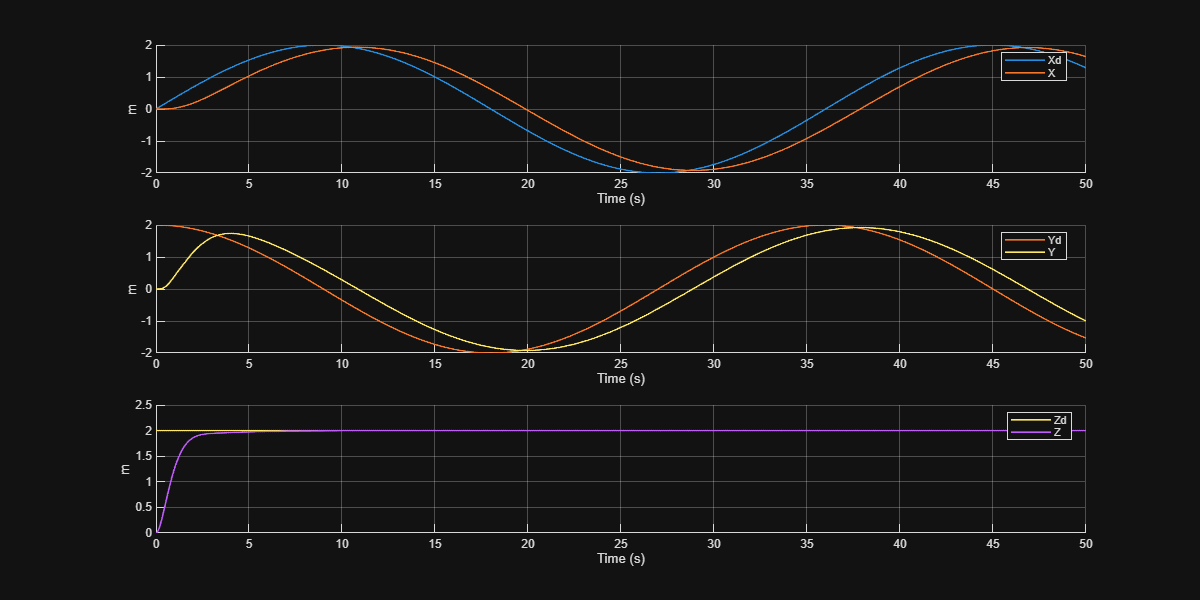

figure('Name', 'Measured - Desired Pose', 'Position', [100 100 1200 600]);

name = {'Xd', 'X', 'Yd', 'Y', 'Zd', 'Z'};
label = {'m', 'm', 'm'};

hold on;

for i = 1:3
    subplot(3,1,i);
    hold on; grid on;
    % Desired Pose
    plot(time(:), ref(i,:), 'Color', colors(i,:), 'LineWidth', 1.2, 'DisplayName', sprintf(name{(i-1)*2+1}));
    % Measured Pose
    plot(time(:), pos(i,:), 'Color', colors(i+1,:), 'LineWidth', 1.2, 'DisplayName', sprintf(name{(i-1)*2+2}));
    xlabel("Time (s)");
    ylabel(label{i});
    legend('Location', 'best');
end

## Attitude

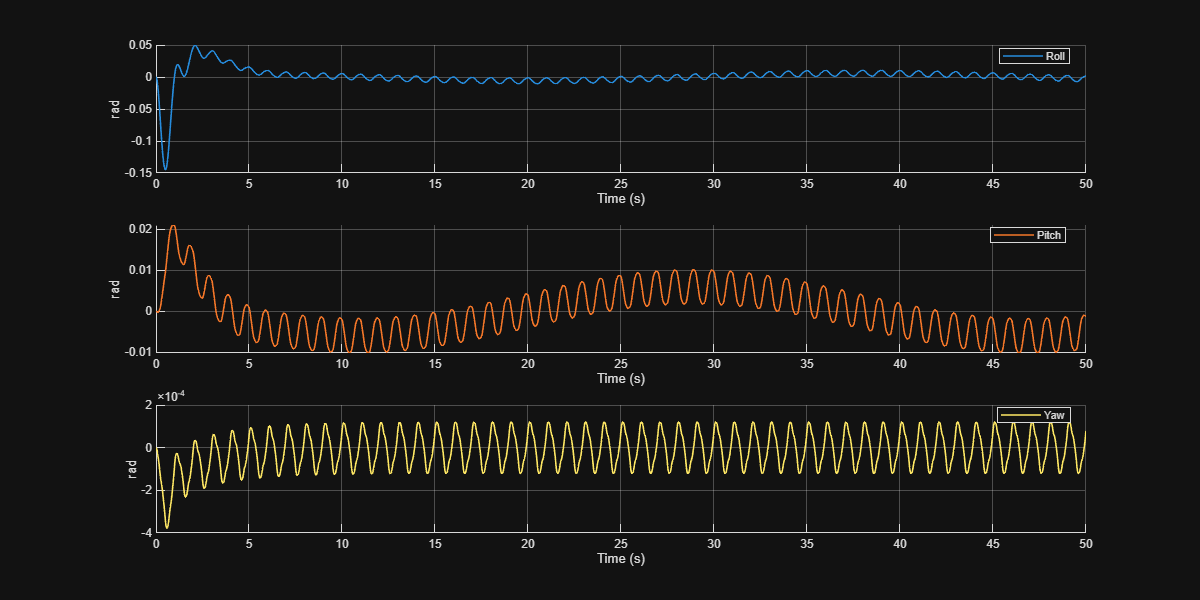

figure('Name', 'Attitude', 'Position', [100 100 1200 600]);

name = {'Roll', 'Pitch', 'Yaw'};
label = {'rad', 'rad', 'rad'};

hold on;

for i = 1:3
    subplot(3,1,i);
    hold on; grid on;
    % Desired Pose
    plot(time(:), att(i,:), 'Color', colors(i,:), 'LineWidth', 1.2, 'DisplayName', sprintf(name{i}));
    xlabel("Time (s)");
    ylabel(label{i});
    legend('Location', 'best');
end

## Controller Command

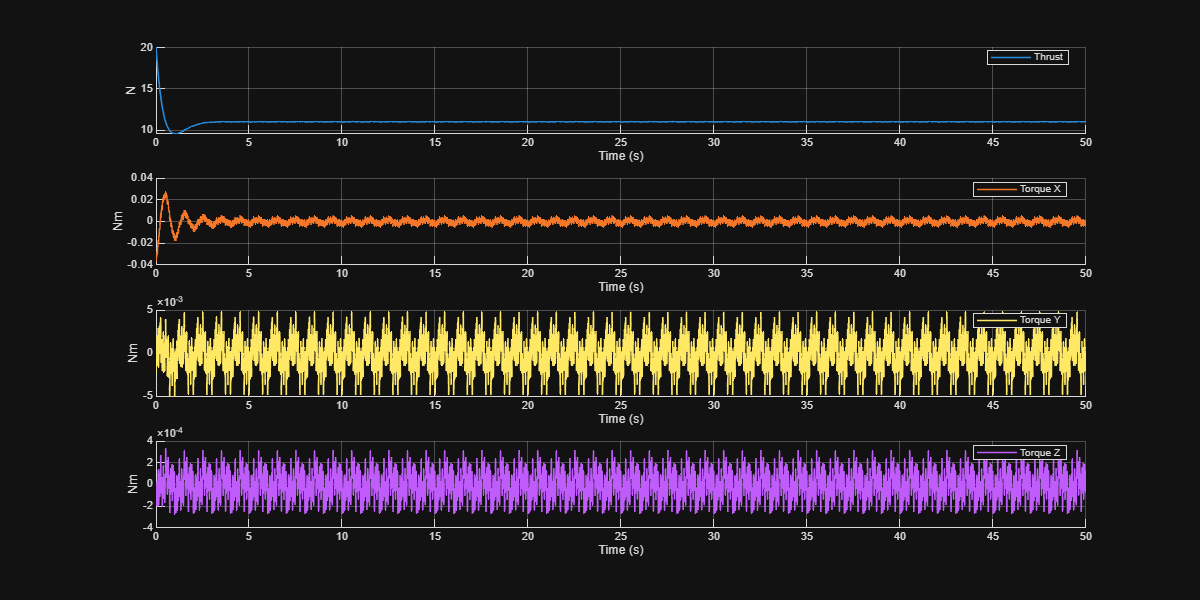

figure('Name', 'Controller Command', 'Position', [100 100 1200 600]);

name = {'Thrust', 'Torque X', 'Torque Y', 'Torque Z'};
label = {'N', 'Nm', 'Nm', 'Nm'};

hold on;

for i = 1:4
    subplot(4,1,i);
    hold on; grid on;
    % Desired Pose
    plot(time(:), controller_cmd(i,:), 'Color', colors(i,:), 'LineWidth', 1.2, 'DisplayName', sprintf(name{i}));
    xlabel("Time (s)");
    ylabel(label{i});
    legend('Location', 'best');
end

## Motor Command

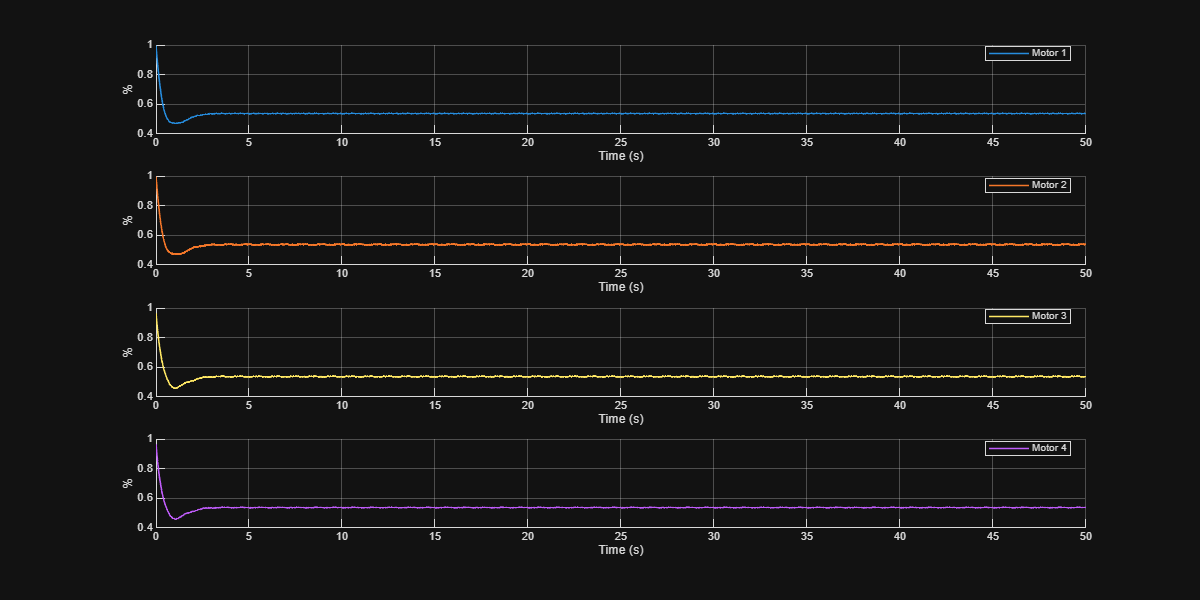

figure('Name', 'Motor Command', 'Position', [100 100 1200 600]);

name = {'Motor 1', 'Motor 2', 'Motor 3', 'Motor 4'};
label = {'%', '%', '%', '%'};

hold on;

for i = 1:4
    subplot(4,1,i);
    hold on; grid on;
    % Desired Pose
    plot(time(:), motor_cmd(i,:), 'Color', colors(i,:), 'LineWidth', 1.2, 'DisplayName', sprintf(name{i}));
    xlabel("Time (s)");
    ylabel(label{i});
    legend('Location', 'best');
end

## Follower

motor_cmd1_data = data.getElement('motor_cmd1');
controller_cmd1_data = data.getElement('controller_cmd1');
ref1_data = data.getElement('ref1');
att1_data = data.getElement('att1');
pos1_data = data.getElement('pos1');


motor_cmd1 = motor_cmd1_data.Values.Data;
controller_cmd1 = controller_cmd1_data.Values.Data;
ref1 = ref1_data.Values.Data;
att1 = att1_data.Values.Data;
pos1 = pos1_data.Values.Data;

motor_cmd1 = reshape(motor_cmd1, size(motor_cmd1,1), size(motor_cmd1,3));
controller_cmd1 = reshape(controller_cmd1, size(controller_cmd1,1), size(controller_cmd1,3));
ref1 = ref1';
att1 = reshape(att1, size(att1,1), size(att1,3));
pos1 = reshape(pos1, size(pos1,1), size(pos1,3));


## Leader - Follower Trajectory

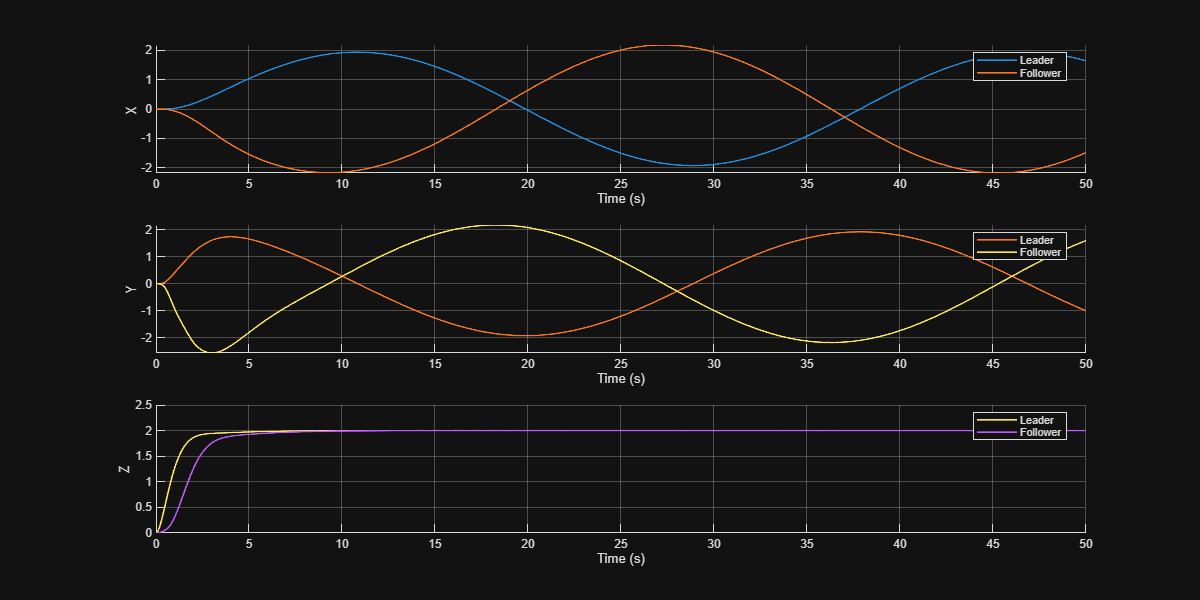

figure('Name', 'Follower Measured Position', 'Position', [100 100 1200 600]);

name = {'Leader', 'Follower'};
label = {'X', 'Y', 'Z'};

hold on;

for i = 1:3
    subplot(3,1,i);
    hold on; grid on;
    % Leader Pose
    plot(time(:), pos(i,:), 'Color', colors(i,:), 'LineWidth', 1.2, 'DisplayName', sprintf(name{1}));
    % Follower Pose
    plot(time(:), pos1(i,:), 'Color', colors(i+1,:), 'LineWidth', 1.2, 'DisplayName', sprintf(name{2}));
    xlabel("Time (s)");
    ylabel(label{i});
    legend('Location', 'best');
end

## Measured - Desired Vector

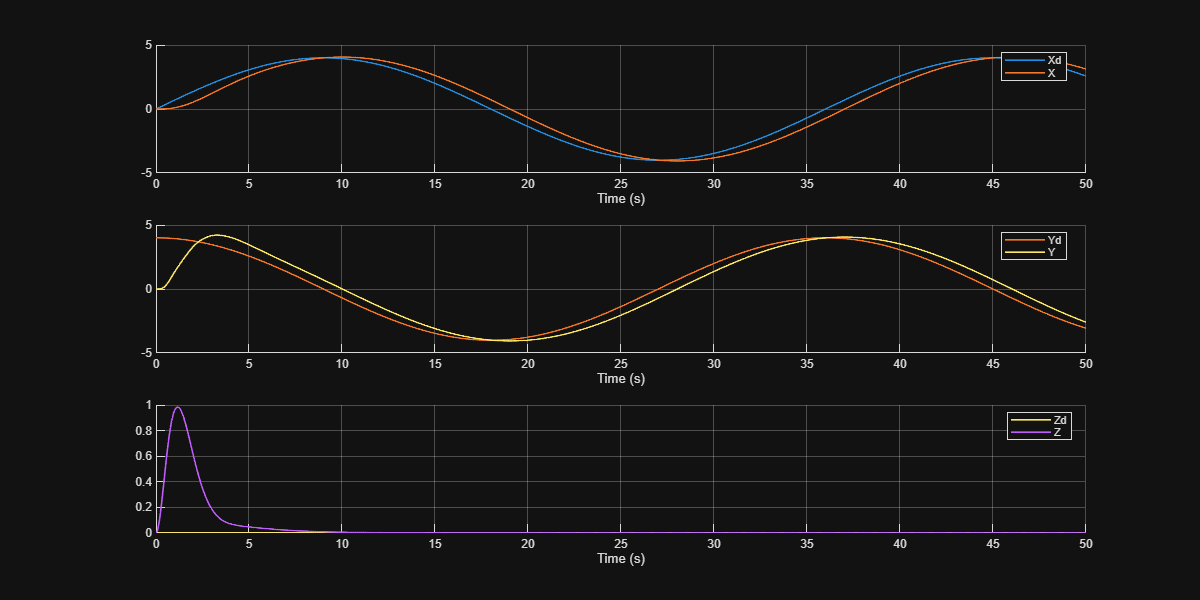

measured_vector = pos - pos1;

figure('Name', 'Follower Measured - Desired Vector', 'Position', [100 100 1200 600]);

name = {'Xd', 'X', 'Yd', 'Y', 'Zd', 'Z'};

hold on;

for i = 1:3
    subplot(3,1,i);
    hold on; grid on;
    % Desired Pose
    plot(time(:), ref1(i,:), 'Color', colors(i,:), 'LineWidth', 1.2, 'DisplayName', sprintf(name{(i-1)*2+1}));
    % Measured Pose
    plot(time(:), measured_vector(i,:), 'Color', colors(i+1,:), 'LineWidth', 1.2, 'DisplayName', sprintf(name{(i-1)*2+2}));
    xlabel("Time (s)");
    legend('Location', 'best');
end